# Laboratorio No. 4

1 Objetivos

2. Requisitos

3. Asignacion del Robot

4. Localización de ruta

5. Características y modelo del robot

addpath 'C:\Program Files\MATLAB\R2020b\toolbox\rvctools'
startup_rvc

Robotics, Vision & Control: (c) Peter Corke 1992-2011 http://www.petercorke.com
- Robotics Toolbox for Matlab (release 9.10)
 - pHRIWARE (release 1.1): pHRIWARE is Copyrighted by Bryan Moutrie (2013-2021) (c)
** Release <!DOCTYPE HTML PUBLIC "-//IETF//DTD HTML 2.0//EN">
<html><head>
<title>301 Moved Permanently</title>
</head><body>
<h1>Moved Permanently</h1>
<p>The document has moved <a href="https://www.petercorke.com/RTB/currentversion.php">here</a>.</p>
</body></html>
 now available

Run rtbdemo to explore the toolbox


clc; 
clear all;
close all;

## 6 Iniciando

### 6.1 Realice el análisis geométrico del robot asignado a través de DH modificado y utilice las funciones de RVC para construir un modelo en alambres.


L1 = 0.089159; L2 = 0.13585; L3 = 0.425; L4 = 0.1197; 
L5 = 0.39225; L6 = 0.093; L7=  0.09465; L8= 0.0823; 
L9 = 0; %L9 Es la distancia del Tool

L(1) = Link('revolute','alpha',0,'a',0,'d',L1,'offset',0,'modified','qlim',[-2*pi 2*pi]);
L(2) = Link('revolute','alpha',-pi/2,'a',0,'d',L2,'offset',0,'modified','qlim',[-2*pi 2*pi]);
L(3) = Link('revolute','alpha',0,'a',L3,'d', -L4,'offset',0,'modified','qlim',[-2*pi 2*pi]);
L(4) = Link('revolute','alpha',0,'a',L5,'d',L6,'offset',-pi,'modified','qlim',[-2*pi 2*pi]);
L(5) = Link('revolute','alpha',pi/2,'a',0,'d',L7,'offset',0,'modified','qlim',[-2*pi 2*pi]);
L(6) = Link('revolute','alpha',-pi/2,'a',0,'d',L8,'offset',0,'modified','qlim',[-2*pi 2*pi]);

UR5_RVC = SerialLink(L,'name', 'RRRRRR')

 
UR5_RVC = 
 
RRRRRR (6 axis, RRRRRR, modDH, fastRNE)                          
                                                                 
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|    0.08916|          0|          0|          0|
|  2|         q2|     0.1358|          0|     -1.571|          0|
|  3|         q3|    -0.1197|      0.425|          0|          0|
|  4|         q4|      0.093|     0.3922|          0|     -3.142|
|  5|         q5|    0.09465|          0|      1.571|          0|
|  6|         q6|     0.0823|          0|     -1.571|          0|
+---+-----------+-----------+-----------+-----------+-----------+
                                                                 
grav =    0  base = 1  0  0  0   tool =  1  0  0  0              
          0         0  1  0  0           0  1  0  0          

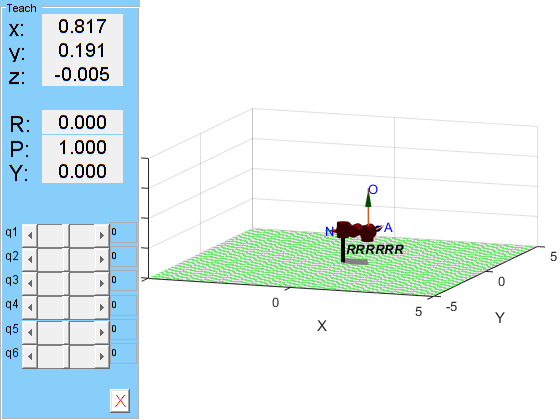

UR5_RVC.plot([0 0 0 0 0 0],'workspace',[-5 5 -5 5 -1 3],'noa','view',[20 10]);
UR5_RVC.teach;

### 6.2 Considerando el robot asignado, construya el modelo del robot utilizando RST.

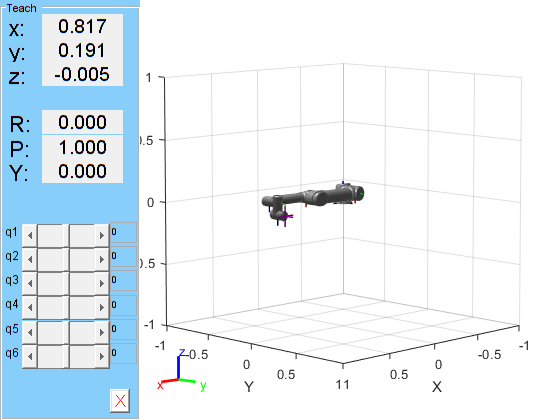

UR5_RST = loadrobot("universalUR5");
show(UR5_RST);

### 6.3 Compare los dos métodos.

### 6.4 Con la hoja técnica del robot, el fabricante provee puntos de calibración. Con la ayuda de la cinemática directa verifique dichos puntos.

## 7 Modelo geométrico directo

### 7.1 Halle el modelo geométrico directo de su robot asignado usando MTH. 

clc; 
clear all;
close all;
syms  q1 q2 q3 q4 q5 q6 L1 L2 L3 L4 L5 L6 L7 L8 L9

L(1) = Link('revolute','alpha',0,'a',0,'d',L1,'offset',0,'modified','qlim',[-2*pi 2*pi]);
L(2) = Link('revolute','alpha',sym(-pi/2),'a',0,'d',L2,'offset',0,'modified','qlim',[-2*pi 2*pi]);
L(3) = Link('revolute','alpha',0,'a',L3,'d', -L4,'offset',0,'modified','qlim',[-2*pi 2*pi]);
L(4) = Link('revolute','alpha',0,'a',L5,'d',L6,'offset',sym(-pi),'modified','qlim',[-2*pi 2*pi]);
L(5) = Link('revolute','alpha',sym(pi/2),'a',0,'d',L7,'offset',0,'modified','qlim',[-2*pi 2*pi]);
L(6) = Link('revolute','alpha',sym(-pi/2),'a',0,'d',L8,'offset',0,'modified','qlim',[-2*pi 2*pi]);

UR5_RVC = SerialLink(L,'name', 'RRRRRR')

 
UR5_RVC = 
 
RRRRRR (6 axis, RRRRRR, modDH, fastRNE)                          
                                                                 
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|         L1|          0|          0|          0|
|  2|         q2|         L2|          0|      -pi/2|          0|
|  3|         q3|        -L4|         L3|          0|          0|
|  4|         q4|         L6|         L5|          0|        -pi|
|  5|         q5|         L7|          0|       pi/2|          0|
|  6|         q6|         L8|          0|      -pi/2|          0|
+---+-----------+-----------+-----------+-----------+-----------+
                                                                 
grav =    0  base = 1  0  0  0   tool =  1  0  0  0              
          0         0  1  0  0           0  1  0  0          

UR5_RVC.tool = [ 1 0 0 0; 0 1 0 0; 0 0 1 L9; 0 0 0 1]

 
UR5_RVC = 
 
RRRRRR (6 axis, RRRRRR, modDH, fastRNE)                          
                                                                 
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|         L1|          0|          0|          0|
|  2|         q2|         L2|          0|      -pi/2|          0|
|  3|         q3|        -L4|         L3|          0|          0|
|  4|         q4|         L6|         L5|          0|        -pi|
|  5|         q5|         L7|          0|       pi/2|          0|
|  6|         q6|         L8|          0|      -pi/2|          0|
+---+-----------+-----------+-----------+-----------+-----------+
                                                                 
grav =    0  base = 1  0  0  0   tool =   1  0  0  0             
          0         0  1  0  0            0  1  0  0         


%Calculo de T_0_1
T_0_1 = L(1).A(q1) 

$$T\_0\_1 = \left(\begin{array}{cccc} \cos\left(q_{1}\right) & -\sin\left(q_{1}\right) & 0 & 0\\ \sin\left(q_{1}\right) & \cos\left(q_{1}\right) & 0 & 0\\ 0 & 0 & 1 & L_{1}\\ 0 & 0 & 0 & 1 \end{array}\right)$$


%Calculo de T_1_2
T_1_2 = L(2).A(q2)

$$T\_1\_2 = \left(\begin{array}{cccc} \cos\left(q_{2}\right) & -\sin\left(q_{2}\right) & 0 & 0\\ 0 & 0 & 1 & L_{2}\\ -\sin\left(q_{2}\right) & -\cos\left(q_{2}\right) & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$


%Calculo de T_2_3
T_2_3 = L(3).A(q3)

$$T\_2\_3 = \left(\begin{array}{cccc} \cos\left(q_{3}\right) & -\sin\left(q_{3}\right) & 0 & L_{3}\\ \sin\left(q_{3}\right) & \cos\left(q_{3}\right) & 0 & 0\\ 0 & 0 & 1 & -L_{4}\\ 0 & 0 & 0 & 1 \end{array}\right)$$


%Calculo de T_3_4
T_3_4 = L(4).A(q4)

$$T\_3\_4 = \left(\begin{array}{cccc} -\cos\left(q_{4}\right) & \sin\left(q_{4}\right) & 0 & L_{5}\\ -\sin\left(q_{4}\right) & -\cos\left(q_{4}\right) & 0 & 0\\ 0 & 0 & 1 & L_{6}\\ 0 & 0 & 0 & 1 \end{array}\right)$$


%Calculo de T_4_5
T_4_5 = L(5).A(q5)

$$T\_4\_5 = \left(\begin{array}{cccc} \cos\left(q_{5}\right) & -\sin\left(q_{5}\right) & 0 & 0\\ 0 & 0 & -1 & -L_{7}\\ \sin\left(q_{5}\right) & \cos\left(q_{5}\right) & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$


%Calculo de T_5_6
T_5_6 = L(6).A(q6)

$$T\_5\_6 = \left(\begin{array}{cccc} \cos\left(q_{6}\right) & -\sin\left(q_{6}\right) & 0 & 0\\ 0 & 0 & 1 & L_{8}\\ -\sin\left(q_{6}\right) & -\cos\left(q_{6}\right) & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$


%Calculo de MTH general

T_0_Tool = T_0_1 * T_1_2 * T_2_3 * T_3_4 * T_4_5 * T_5_6 * UR5_RVC.tool

### 7.2 Haciendo uso del modelo cinemático directo obtenga los valores de posición y de orientación en coordenadas generalizadas del efector final de su robot asignado para los siguientes valores articulares: 

L1 = 0.089159; L2 = 0.13585; L3 = 0.425; L4 = 0.1197; 
L5 = 0.39225; L6 = 0.093; L7=  0.09465; L8= 0.0823; 
L9 = 0; %L9 Es la distancia del Tool

L(1) = Link('revolute','alpha',0,'a',0,'d',L1,'offset',0,'modified','qlim',[-2*pi 2*pi]);
L(2) = Link('revolute','alpha',-pi/2,'a',0,'d',L2,'offset',0,'modified','qlim',[-2*pi 2*pi]);
L(3) = Link('revolute','alpha',0,'a',L3,'d', -L4,'offset',0,'modified','qlim',[-2*pi 2*pi]);
L(4) = Link('revolute','alpha',0,'a',L5,'d',L6,'offset',-pi,'modified','qlim',[-2*pi 2*pi]);
L(5) = Link('revolute','alpha',pi/2,'a',0,'d',L7,'offset',0,'modified','qlim',[-2*pi 2*pi]);
L(6) = Link('revolute','alpha',-pi/2,'a',0,'d',L8,'offset',0,'modified','qlim',[-2*pi 2*pi]);

 UR5_RVC = SerialLink(L,'name', 'RRRRRR')

 
UR5_RVC = 
 
RRRRRR (6 axis, RRRRRR, modDH, fastRNE)                          
                                                                 
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|    0.08916|          0|          0|          0|
|  2|         q2|     0.1358|          0|     -1.571|          0|
|  3|         q3|    -0.1197|      0.425|          0|          0|
|  4|         q4|      0.093|     0.3922|          0|     -3.142|
|  5|         q5|    0.09465|          0|      1.571|          0|
|  6|         q6|     0.0823|          0|     -1.571|          0|
+---+-----------+-----------+-----------+-----------+-----------+
                                                                 
grav =    0  base = 1  0  0  0   tool =  1  0  0  0              
          0         0  1  0  0           0  1  0  0          

 UR5_RVC.tool = [ 1 0 0 0; 0 1 0 0; 0 0 1 L9; 0 0 0 1]

 
UR5_RVC = 
 
RRRRRR (6 axis, RRRRRR, modDH, fastRNE)                          
                                                                 
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|    0.08916|          0|          0|          0|
|  2|         q2|     0.1358|          0|     -1.571|          0|
|  3|         q3|    -0.1197|      0.425|          0|          0|
|  4|         q4|      0.093|     0.3922|          0|     -3.142|
|  5|         q5|    0.09465|          0|      1.571|          0|
|  6|         q6|     0.0823|          0|     -1.571|          0|
+---+-----------+-----------+-----------+-----------+-----------+
                                                                 
grav =    0  base = 1  0  0  0   tool =  1  0  0  0              
          0         0  1  0  0           0  1  0  0          


% Caso 1

T_0_1 = L(1).A(0.5); T_1_2 = L(2).A(0.2); T_2_3 = L(3).A(0.4);
T_3_4 = L(4).A(0.5); T_4_5 = L(5).A(0);   T_5_6 = L(6).A(1.5);

T_0_Tool = T_0_1 * T_1_2 * T_2_3 * T_3_4 * T_4_5 * T_5_6 * UR5_RVC.tool

T_0_Tool =     0.7520    0.4524   -0.4794    0.4838
    0.4108    0.2471    0.8776    0.4825
    0.5155   -0.8569    0.0000   -0.2597
         0         0         0    1.0000



vPosicion=T_0_Tool(1:3,4)

vPosicion =     0.4838
    0.4825
   -0.2597



mRotacion = T_0_Tool(1:3,1:3) % Extraemos la matriz de rotacion de la matriz obtenida de Transformacion

mRotacion =     0.7520    0.4524   -0.4794
    0.4108    0.2471    0.8776
    0.5155   -0.8569    0.0000


roll = atan2(-mRotacion(2,3),mRotacion(3,3))*(180/pi)

roll = -90

sr = sin(degtorad(roll));
cr = cos(degtorad(roll));
pitch= atan2(mRotacion(1,3),cr*mRotacion(3,3)-sr*mRotacion(2,3))*(180/pi)

pitch = -28.6479

yaw = atan2(-mRotacion(1,2),mRotacion(1,1))*(180/pi)

yaw = -31.0310


cGeneral1 = [vPosicion', roll, pitch, yaw]

cGeneral1 =     0.4838    0.4825   -0.2597  -90.0000  -28.6479  -31.0310



% Caso 2

T_0_1 = L(1).A(-pi/2); T_1_2 = L(2).A(0.3); T_2_3 = L(3).A(0);
T_3_4 = L(4).A(pi/2); T_4_5 = L(5).A(0.4);   T_5_6 = L(6).A(1.2);

T_0_Tool = T_0_1 * T_1_2 * T_2_3 * T_3_4 * T_4_5 * T_5_6 * UR5_RVC.tool

T_0_Tool =     0.1411   -0.3630    0.9211    0.1850
   -0.9890   -0.0925    0.1151   -0.6809
    0.0434   -0.9272   -0.3720   -0.1550
         0         0         0    1.0000



vPosicion=T_0_Tool(1:3,4)

vPosicion =     0.1850
   -0.6809
   -0.1550



mRotacion = T_0_Tool(1:3,1:3) % Extraemos la matriz de rotacion de la matriz obtenida de Transformacion

mRotacion =     0.1411   -0.3630    0.9211
   -0.9890   -0.0925    0.1151
    0.0434   -0.9272   -0.3720


roll = atan2(-mRotacion(2,3),mRotacion(3,3))*(180/pi)

roll = -162.8113

sr = sin(degtorad(roll));
cr = cos(degtorad(roll));
pitch= atan2(mRotacion(1,3),cr*mRotacion(3,3)-sr*mRotacion(2,3))*(180/pi)

pitch = 67.0817

yaw = atan2(-mRotacion(1,2),mRotacion(1,1))*(180/pi)

yaw = 68.7549


cGeneral2 = [vPosicion', roll, pitch, yaw]

cGeneral2 =     0.1850   -0.6809   -0.1550 -162.8113   67.0817   68.7549



% Caso 3

T_0_1 = L(1).A(0); T_1_2 = L(2).A(1); T_2_3 = L(3).A(-0.5);
T_3_4 = L(4).A(2); T_4_5 = L(5).A(1);   T_5_6 = L(6).A(0.5);

T_0_Tool = T_0_1 * T_1_2 * T_2_3 * T_3_4 * T_4_5 * T_5_6 * UR5_RVC.tool

T_0_Tool =     0.6668    0.3177   -0.6741    0.4617
    0.7385   -0.4034    0.5403    0.1536
   -0.1003   -0.8581   -0.5036   -0.4221
         0         0         0    1.0000



vPosicion=T_0_Tool(1:3,4)

vPosicion =     0.4617
    0.1536
   -0.4221



mRotacion = T_0_Tool(1:3,1:3) % Extraemos la matriz de rotacion de la matriz obtenida de Transformacion

mRotacion =     0.6668    0.3177   -0.6741
    0.7385   -0.4034    0.5403
   -0.1003   -0.8581   -0.5036


roll = atan2(-mRotacion(2,3),mRotacion(3,3))*(180/pi)

roll = -132.9862

sr = sin(degtorad(roll));
cr = cos(degtorad(roll));
pitch= atan2(mRotacion(1,3),cr*mRotacion(3,3)-sr*mRotacion(2,3))*(180/pi)

pitch = -42.3873

yaw = atan2(-mRotacion(1,2),mRotacion(1,1))*(180/pi)

yaw = -25.4748


cGeneral3 = [vPosicion', roll, pitch, yaw]

cGeneral3 =     0.4617    0.1536   -0.4221 -132.9862  -42.3873  -25.4748



% Caso 4

T_0_1 = L(1).A(-1); T_1_2 = L(2).A(-0.3); T_2_3 = L(3).A(-pi/5);
T_3_4 = L(4).A(0.4); T_4_5 = L(5).A(0.2);   T_5_6 = L(6).A(1);

T_0_Tool = T_0_1 * T_1_2 * T_2_3 * T_3_4 * T_4_5 * T_5_6 * UR5_RVC.tool

T_0_Tool =    -0.3860    0.0970    0.9174    0.5395
    0.7998   -0.4605    0.3852   -0.4889
    0.4598    0.8824    0.1001    0.4553
         0         0         0    1.0000



vPosicion=T_0_Tool(1:3,4)

vPosicion =     0.5395
   -0.4889
    0.4553



mRotacion = T_0_Tool(1:3,1:3) % Extraemos la matriz de rotacion de la matriz obtenida de Transformacion

mRotacion =    -0.3860    0.0970    0.9174
    0.7998   -0.4605    0.3852
    0.4598    0.8824    0.1001


roll = atan2(-mRotacion(2,3),mRotacion(3,3))*(180/pi)

roll = -75.4249

sr = sin(degtorad(roll));
cr = cos(degtorad(roll));
pitch= atan2(mRotacion(1,3),cr*mRotacion(3,3)-sr*mRotacion(2,3))*(180/pi)

pitch = 66.5494

yaw = atan2(-mRotacion(1,2),mRotacion(1,1))*(180/pi)

yaw = -165.8915


cGeneral4 = [vPosicion', roll, pitch, yaw]

cGeneral4 =     0.5395   -0.4889    0.4553  -75.4249   66.5494 -165.8915


### 7.3 Haga uso de las funciones de cinemática directa de ambos toolboxes y compruebe los resultados anteriores. 

%% Haciendo uso del Toolbox de Peter Corke

% Caso 1

q = [0.5 0.2 0.4 0.5 0 1.5];
T_RVC1 = UR5_RVC.fkine(q) % Cinemática directa del robot en el caso 1

T_RVC1 =     0.7520    0.4524   -0.4794    0.4838
    0.4108    0.2471    0.8776    0.4825
    0.5155   -0.8569    0.0000   -0.2597
         0         0         0    1.0000



gen_RVC1=[transl(T_RVC1)', tr2rpy(T_RVC1,'deg')] % Coordenadas generalizadas de Posicion y orientacion en ángulos RPY

gen_RVC1 =     0.4838    0.4825   -0.2597  -90.0000  -28.6479  -31.0310



% Caso 2

q = [-pi/2 0.3 0 pi/2 0.4 1.2];
T_RVC2 = UR5_RVC.fkine(q) % Cinemática directa del robot en el caso 2

T_RVC2 =     0.1411   -0.3630    0.9211    0.1850
   -0.9890   -0.0925    0.1151   -0.6809
    0.0434   -0.9272   -0.3720   -0.1550
         0         0         0    1.0000



gen_RVC2=[transl(T_RVC2)', tr2rpy(T_RVC2,'deg')] % Coordenadas generalizadas de Posicion y orientacion en ángulos RPY

gen_RVC2 =     0.1850   -0.6809   -0.1550 -162.8113   67.0817   68.7549



% Caso 3

q = [0 1 -0.5 2 1 0.5];
T_RVC3 = UR5_RVC.fkine(q) % Cinemática directa del robot en el caso 3

T_RVC3 =     0.6668    0.3177   -0.6741    0.4617
    0.7385   -0.4034    0.5403    0.1536
   -0.1003   -0.8581   -0.5036   -0.4221
         0         0         0    1.0000


gen_RVC3=[transl(T_RVC3)', tr2rpy(T_RVC3,'deg')] % Coordenadas generalizadas de Posicion y orientacion en ángulos RPY

gen_RVC3 =     0.4617    0.1536   -0.4221 -132.9862  -42.3873  -25.4748



% Caso 4

q = [-1 -0.3 -pi/5 0.4 0.2 1];
T_RVC4 = UR5_RVC.fkine(q) % Cinemática directa del robot en el caso 4

T_RVC4 =    -0.3860    0.0970    0.9174    0.5395
    0.7998   -0.4605    0.3852   -0.4889
    0.4598    0.8824    0.1001    0.4553
         0         0         0    1.0000


gen_RVC4=[transl(T_RVC4)', tr2rpy(T_RVC4,'deg')] % Coordenadas generalizadas de Posicion y orientacion en ángulos RPY

gen_RVC4 =     0.5395   -0.4889    0.4553  -75.4249   66.5494 -165.8915



%% Usando el Toolbox de Matlab

UR5_RST = loadrobot("universalUR5","Gravity", [0 0 -9.81]);
UR5_RST.DataFormat = 'row';
% Caso 1

q = [0.5 0.2 0.4 0.5 0 1.5];
T_RST1=getTransform(UR5_RST,q,'tool0')

T_RST1 =     0.7520    0.4524   -0.4794    0.4838
    0.4108    0.2471    0.8776    0.4825
    0.5155   -0.8569    0.0000   -0.2597
         0         0         0    1.0000


gen_RST1=[transl(T_RST1)', tr2rpy(T_RST1,'deg')]

gen_RST1 =     0.4838    0.4825   -0.2597  -90.0000  -28.6479  -31.0310



% Caso 2

q = [-pi/2 0.3 0 pi/2 0.4 1.2];
T_RST2=getTransform(UR5_RST,q,'tool0')

T_RST2 =     0.1411   -0.3630    0.9211    0.1850
   -0.9890   -0.0925    0.1151   -0.6809
    0.0434   -0.9272   -0.3720   -0.1550
         0         0         0    1.0000


gen_RST2=[transl(T_RST2)', tr2rpy(T_RST2,'deg')]

gen_RST2 =     0.1850   -0.6809   -0.1550 -162.8113   67.0817   68.7549



% Caso 3

q = [0 1 -0.5 2 1 0.5];
T_RST3=getTransform(UR5_RST,q,'tool0')

T_RST3 =     0.6668    0.3177   -0.6741    0.4617
    0.7385   -0.4034    0.5403    0.1536
   -0.1003   -0.8581   -0.5036   -0.4221
         0         0         0    1.0000


gen_RST3=[transl(T_RST3)', tr2rpy(T_RST3,'deg')]

gen_RST3 =     0.4617    0.1536   -0.4221 -132.9862  -42.3873  -25.4748



% Caso 4

q = [-1 -0.3 -pi/5 0.4 0.2 1];
T_RST4=getTransform(UR5_RST,q,'tool0')

T_RST4 =    -0.3860    0.0970    0.9174    0.5395
    0.7998   -0.4605    0.3852   -0.4889
    0.4598    0.8824    0.1001    0.4553
         0         0         0    1.0000


gen_RST4=[transl(T_RST4)', tr2rpy(T_RST4,'deg')]

gen_RST4 =     0.5395   -0.4889    0.4553  -75.4249   66.5494 -165.8915


### 7.4 Compare los métodos

### 7.5 Elija uno de los métodos anteriormente usados y desarrolle una GUI que permita mover cada articulación mediante controles tipo Slider, visualizar el robot y la posición del efector final.

### 7.6 En el informe incluya capturas de pantalla verificando las posiciones EF y las articulaciones.

## 8 Modelo Geométrico inverso

### 8.1 Determine el modelo geométrico inverso del robot asignado haciendo uso de la metodología explicada en clase.

### 8.2 En las soluciones de la inversa incluya consideraciones respecto a multiplicidad de soluciones.

#### 8.3 Haga uso de las funciones del RVC para hallar la cinemática inversa de su robot asignado y compruebe los resultados del punto anterior. Ya que existen varias funciones en el Toolbox explique: 

#### 8.3.1 ¿Cuál es la diferencia entre estas funciones? 

El toolbox RVC cuenta con 7 funciones para el uso de la cinematica inversa: ikcon, ikine, ikine3, ikine6s, ikine_sym, ikinem,ikunc. 

***ikcon*** usa cinematica inversa con un rango limitado de movimiento en las articulaciones

***ikine3, ikine6s, ikine*** usa cinematica inversa usando métodos numéricos, bajo la condicion que el robot serial usa una muñeca esferica, en el caso ikine3 hace la cinematica inversa para un robot de posicion de 3 grados de libertad sin esta muñeca esferica, el caso ikine6s esta optimizado analiticamente para robots de 6 grados de libertad con muñeca esferica

***ikine_sym*** devuelve la solucion simbolica de la solucion como un vector de Nx1 donde cada elemento muestra la solucion por cada articulación del robot serial

***ikinem*** hace una solucion numerica por minimizacion en la configuracion, depende intrinsecamente de una configuracion inicial definida en un vector q y usa el metodo de minimizacion Levenberg_Marquadt

***ikunc*** hace una solucion numerica similar a la anterior, pero usa algoritmos de optimizacion, depende del toolbox de optimizacion de matlab y retorna además el error del procedimiento 

#### 8.3.2 ¿Cuál debe usar para su robot y por qué?

Se usa la función ikunc debido a que al probar las funciones posibles, esta fue la que mejor dió resultados al compararlo entre ellas.  No se usa la función ikine ya que estas tiende a hacer muchas iteraciones y su aproximación es mala.

A continuación se lista un código con el que se realizaron las pruebas:

L1 = 0.089159; L2 = 0.13585; L3 = 0.425; L4 = 0.1197; 
L5 = 0.39225; L6 = 0.093; L7=  0.09465; L8= 0.0823; 

L9 = 0; %L9 Es la distancia del Tool

L(1) = Link('revolute','alpha',0,'a',0,'d',L1,'offset',0,'modified','qlim',[-2*pi 2*pi]);
L(2) = Link('revolute','alpha',-pi/2,'a',0,'d',L2,'offset',0,'modified','qlim',[-2*pi 2*pi]);
L(3) = Link('revolute','alpha',0,'a',L3,'d', -L4,'offset',0,'modified','qlim',[-2*pi 2*pi]);
L(4) = Link('revolute','alpha',0,'a',L5,'d',L6,'offset',-pi,'modified','qlim',[-2*pi 2*pi]);
L(5) = Link('revolute','alpha',pi/2,'a',0,'d',L7,'offset',0,'modified','qlim',[-2*pi 2*pi]);
L(6) = Link('revolute','alpha',-pi/2,'a',0,'d',L8,'offset',0,'modified','qlim',[-2*pi 2*pi]);

UR5_RVC = SerialLink(L,'name', 'RRRRRR')

 
UR5_RVC = 
 
RRRRRR (6 axis, RRRRRR, modDH, fastRNE)                          
                                                                 
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|    0.08916|          0|          0|          0|
|  2|         q2|     0.1358|          0|     -1.571|          0|
|  3|         q3|    -0.1197|      0.425|          0|          0|
|  4|         q4|      0.093|     0.3922|          0|     -3.142|
|  5|         q5|    0.09465|          0|      1.571|          0|
|  6|         q6|     0.0823|          0|     -1.571|          0|
+---+-----------+-----------+-----------+-----------+-----------+
                                                                 
grav =    0  base = 1  0  0  0   tool =  1  0  0  0              
          0         0  1  0  0           0  1  0  0          

%UR5_RVC.tool = [ 0 -1 0 0; 1 0 0 0; 0 0 1 L9; 0 0 0 1]
UR5_RVC.tool = [ 1 0 0 0; 0 1 0 0; 0 0 1 L9; 0 0 0 1]

 
UR5_RVC = 
 
RRRRRR (6 axis, RRRRRR, modDH, fastRNE)                          
                                                                 
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|    0.08916|          0|          0|          0|
|  2|         q2|     0.1358|          0|     -1.571|          0|
|  3|         q3|    -0.1197|      0.425|          0|          0|
|  4|         q4|      0.093|     0.3922|          0|     -3.142|
|  5|         q5|    0.09465|          0|      1.571|          0|
|  6|         q6|     0.0823|          0|     -1.571|          0|
+---+-----------+-----------+-----------+-----------+-----------+
                                                                 
grav =    0  base = 1  0  0  0   tool =  1  0  0  0              
          0         0  1  0  0           0  1  0  0          


q_pred=[pi/6 pi/6 pi/6 pi/6 pi/6 pi/6]

q_pred =     0.5236    0.5236    0.5236    0.5236    0.5236    0.5236



T_0_1 = L(1).A(q_pred(1)); T_1_2 = L(2).A(q_pred(2)); T_2_3 = L(3).A(q_pred(3));
T_3_4 = L(4).A(q_pred(4)); T_4_5 = L(5).A(q_pred(5));   T_5_6 = L(6).A(q_pred(6));

T_0_Tool = T_0_1 * T_1_2 * T_2_3 * T_3_4 * T_4_5 * T_5_6 * UR5_RVC.tool

T_0_Tool =     0.2165    0.8750   -0.4330    0.3164
    0.6250    0.2165    0.7500    0.3910
    0.7500   -0.4330   -0.5000   -0.5042
         0         0         0    1.0000



q_prueba=[0.1 0.1 0.1 0.1 0.1 0.1]

q_prueba =     0.1000    0.1000    0.1000    0.1000    0.1000    0.1000



% A=UR5_RVC.ikcon(T_0_Tool, q_prueba) % sirve nivel intermedio

% B=UR5_RVC.ikinem(T_0_Tool, q_prueba) % sirve, pero peor

% C=UR5_RVC.ikunc(T_0_Tool, q_prueba) % Sirve nivel avanzado ***

Concluida la prueba, se demuestra la eficiencia de ***ikunc***


% Punto de prueba 1

G_prueba=[0.2 0.15 0.4 15 30 45]

G_prueba =     0.2000    0.1500    0.4000   15.0000   30.0000   45.0000


     % Se crea la matriz de transformacion a partir del vector de
     % coordenadas generalizadas usando funciondes del toolbox RVC
T_prueba=rt2tr(rpy2r(G_prueba(4),G_prueba(5),G_prueba(6),'deg'), [G_prueba(1) G_prueba(2) G_prueba(3)]')

T_prueba =     0.6124   -0.6124    0.5000    0.2000
    0.7745    0.5915   -0.2241    0.1500
   -0.1585    0.5245    0.8365    0.4000
         0         0         0    1.0000



Solucion1=UR5_RVC.ikunc(T_prueba,q_prueba)

Solucion1 =     0.3238   -0.0845   -2.3753    1.3377    1.9515   -0.9508



% Punto de prueba 2

G_prueba=[-0.3 0.2 -0.2 75 -20 0]

G_prueba =    -0.3000    0.2000   -0.2000   75.0000  -20.0000         0


     % Se crea la matriz de transformacion a partir del vector de
     % coordenadas generalizadas usando funciondes del toolbox RVC
T_prueba=rt2tr(rpy2r(G_prueba(4),G_prueba(5),G_prueba(6),'deg'), [G_prueba(1) G_prueba(2) G_prueba(3)]')

T_prueba =     0.9397         0   -0.3420   -0.3000
   -0.3304    0.2588   -0.9077    0.2000
    0.0885    0.9659    0.2432   -0.2000
         0         0         0    1.0000



Solucion2=UR5_RVC.ikunc(T_prueba,q_prueba)

Solucion2 =     2.0647   -0.4146    1.9458   -1.1666   -0.7504   -0.1809



% Punto de prueba 3

G_prueba=[-0.35 0.3 0.1 -10 35 50]

G_prueba =    -0.3500    0.3000    0.1000  -10.0000   35.0000   50.0000


     % Se crea la matriz de transformacion a partir del vector de
     % coordenadas generalizadas usando funciondes del toolbox RVC
T_prueba=rt2tr(rpy2r(G_prueba(4),G_prueba(5),G_prueba(6),'deg'), [G_prueba(1) G_prueba(2) G_prueba(3)]')

T_prueba =     0.5265   -0.6275    0.5736   -0.3500
    0.6904    0.7093    0.1422    0.3000
   -0.4961    0.3211    0.8067    0.1000
         0         0         0    1.0000



Solucion3=UR5_RVC.ikunc(T_prueba,q_prueba)

Solucion3 =     2.2895    1.2083   -2.1269   -0.9758    2.1239   -3.1354



% Punto de prueba 4

G_prueba=[0.3 -0.4 0 90 -45 -45]

G_prueba =     0.3000   -0.4000         0   90.0000  -45.0000  -45.0000


     % Se crea la matriz de transformacion a partir del vector de
     % coordenadas generalizadas usando funciondes del toolbox RVC
T_prueba=rt2tr(rpy2r(G_prueba(4),G_prueba(5),G_prueba(6),'deg'), [G_prueba(1) G_prueba(2) G_prueba(3)]')

T_prueba =     0.5000    0.5000   -0.7071    0.3000
   -0.5000   -0.5000   -0.7071   -0.4000
   -0.7071    0.7071    0.0000         0
         0         0         0    1.0000



Solucion4=UR5_RVC.ikunc(T_prueba,q_prueba)

Solucion4 =    -0.9843   -0.4745    1.7746    1.8415   -2.9427    2.3562


#### 8.4 Haga uso del RST para hallar la cinemática inversa de su robot asignado y compruebe los resultados anteriores.  

UR5_RST = loadrobot("universalUR5","Gravity", [0 0 -9.81]);
UR5_RST.DataFormat = 'row';
ik = inverseKinematics('RigidBodyTree',UR5_RST)

ik =   inverseKinematics with properties:

       RigidBodyTree: [1×1 rigidBodyTree]
     SolverAlgorithm: 'BFGSGradientProjection'
    SolverParameters: [1×1 struct]



%Caso 1
G_prueba=[0.2 0.15 0.4 15 30 45]

G_prueba =     0.2000    0.1500    0.4000   15.0000   30.0000   45.0000


T_prueba=rt2tr(rpy2r(G_prueba(4),G_prueba(5),G_prueba(6),'deg'), [G_prueba(1) G_prueba(2) G_prueba(3)]');
puntoIncial = [0.1 0.1 0.1 0.1 0.1 0.1];
weights = [0.25 0.25 0.25 1 1 1];
[configSoln1,solnInfo] = ik('tool0',T_prueba,weights,puntoIncial)

configSoln1 =     0.3238   -0.0845   -2.3753    1.3377    1.9515   -0.9508


solnInfo = struct with fields:
           Iterations: 30
    NumRandomRestarts: 0
        PoseErrorNorm: 7.1548e-09
             ExitFlag: 1
               Status: 'success'



%Caso 2
G_prueba=[-0.3 0.2 -0.2 75 -20 0]

G_prueba =    -0.3000    0.2000   -0.2000   75.0000  -20.0000         0


T_prueba=rt2tr(rpy2r(G_prueba(4),G_prueba(5),G_prueba(6),'deg'), [G_prueba(1) G_prueba(2) G_prueba(3)]');
puntoIncial = [0.1 0.1 0.1 0.1 0.1 0.1];
weights = [0.25 0.25 0.25 1 1 1];
[configSoln2,solnInfo] = ik('tool0',T_prueba,weights,puntoIncial)

configSoln2 = 1×6
    2.0647   -0.4146    1.9458   -1.1666   -0.7504   -0.1809


solnInfo = struct with fields:
           Iterations: 32
    NumRandomRestarts: 0
        PoseErrorNorm: 1.3239e-08
             ExitFlag: 1
               Status: 'success'



%Caso 3
G_prueba=[-0.35 0.3 0.1 -10 35 50]

G_prueba = 1×6
   -0.3500    0.3000    0.1000  -10.0000   35.0000   50.0000


T_prueba=rt2tr(rpy2r(G_prueba(4),G_prueba(5),G_prueba(6),'deg'), [G_prueba(1) G_prueba(2) G_prueba(3)]');
puntoIncial = [0.1 0.1 0.1 0.1 0.1 0.1];
weights = [0.25 0.25 0.25 1 1 1];
[configSoln3,solnInfo] = ik('tool0',T_prueba,weights,puntoIncial)

configSoln3 = 1×6
    2.2895    1.2083   -2.1269   -0.9758   -4.1592   -3.1354


solnInfo = struct with fields:
           Iterations: 94
    NumRandomRestarts: 2
        PoseErrorNorm: 9.2979e-09
             ExitFlag: 1
               Status: 'success'



%Caso 4
G_prueba=[0.3 -0.4 0 90 -45 -45]

G_prueba = 1×6
    0.3000   -0.4000         0   90.0000  -45.0000  -45.0000


T_prueba=rt2tr(rpy2r(G_prueba(4),G_prueba(5),G_prueba(6),'deg'), [G_prueba(1) G_prueba(2) G_prueba(3)]');
puntoIncial = [0.1 0.1 0.1 0.1 0.1 0.1];
weights = [0.25 0.25 0.25 1 1 1];
[configSoln4,solnInfo] = ik('tool0',T_prueba,weights,puntoIncial)

configSoln4 = 1×6
   -0.9843   -0.4745    1.7746    1.8415   -2.9427    2.3562


solnInfo = struct with fields:
           Iterations: 32
    NumRandomRestarts: 0
        PoseErrorNorm: 2.2715e-09
             ExitFlag: 1
               Status: 'success'


## 9. Considerando que para que el robot ejecute los movimientos, se desea establecer una relación entre las velocidades del efector final y las articulaciones: 

### 9.1 Con los valores numéricos de longitudes y desplazamientos de los eslabones del robot asignado obtenga el Jacobiano (como una matriz de valores númericos, NO simbólico) en función de los ángulos de articulación.

clear
L1 = 0.089159; L2 = 0.13585; L3 = 0.425; L4 = 0.1197; 
L5 = 0.39225; L6 = 0.093; L7=  0.09465; L8= 0.0823; 

L9 = 0; %L9 Es la distancia del Tool

L(1) = Link('revolute','alpha',0,'a',0,'d',L1,'offset',0,'modified','qlim',[-2*pi 2*pi]);
L(2) = Link('revolute','alpha',-pi/2,'a',0,'d',L2,'offset',0,'modified','qlim',[-2*pi 2*pi]);
L(3) = Link('revolute','alpha',0,'a',L3,'d', -L4,'offset',0,'modified','qlim',[-2*pi 2*pi]);
L(4) = Link('revolute','alpha',0,'a',L5,'d',L6,'offset',-pi,'modified','qlim',[-2*pi 2*pi]);
L(5) = Link('revolute','alpha',pi/2,'a',0,'d',L7,'offset',0,'modified','qlim',[-2*pi 2*pi]);
L(6) = Link('revolute','alpha',-pi/2,'a',0,'d',L8,'offset',0,'modified','qlim',[-2*pi 2*pi]);

UR5_RVC = SerialLink(L,'name', 'RRRRRR')

 
UR5_RVC = 
 
RRRRRR (6 axis, RRRRRR, modDH, fastRNE)                          
                                                                 
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|    0.08916|          0|          0|          0|
|  2|         q2|     0.1358|          0|     -1.571|          0|
|  3|         q3|    -0.1197|      0.425|          0|          0|
|  4|         q4|      0.093|     0.3922|          0|     -3.142|
|  5|         q5|    0.09465|          0|      1.571|          0|
|  6|         q6|     0.0823|          0|     -1.571|          0|
+---+-----------+-----------+-----------+-----------+-----------+
                                                                 
grav =    0  base = 1  0  0  0   tool =  1  0  0  0              
          0         0  1  0  0           0  1  0  0          

%UR5_RVC.tool = [ 0 -1 0 0; 1 0 0 0; 0 0 1 L9; 0 0 0 1]
UR5_RVC.tool = [ 1 0 0 0; 0 1 0 0; 0 0 1 L9; 0 0 0 1]

 
UR5_RVC = 
 
RRRRRR (6 axis, RRRRRR, modDH, fastRNE)                          
                                                                 
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|    0.08916|          0|          0|          0|
|  2|         q2|     0.1358|          0|     -1.571|          0|
|  3|         q3|    -0.1197|      0.425|          0|          0|
|  4|         q4|      0.093|     0.3922|          0|     -3.142|
|  5|         q5|    0.09465|          0|      1.571|          0|
|  6|         q6|     0.0823|          0|     -1.571|          0|
+---+-----------+-----------+-----------+-----------+-----------+
                                                                 
grav =    0  base = 1  0  0  0   tool =  1  0  0  0              
          0         0  1  0  0           0  1  0  0          


% Vector de valores de prueba de Q, para obtener una matriz Jacobiana numerica

q=[0 0 0 0 0 0] 

q =      0     0     0     0     0     0



% Matrices de Transformacion Homogenea

A_01=L(1).A(q(1)); A_12=L(2).A(q(2)); A_23=L(3).A(q(3)); A_34=L(4).A(q(4)); A_45=L(5).A(q(5)); A_56=L(6).A(q(6));
A_6T=UR5_RVC.tool;

% Matriz de Transformacion
A_0T=fkine(UR5_RVC,q)

A_0T =    -1.0000    0.0000         0    0.8173
   -0.0000   -0.0000    1.0000    0.1915
    0.0000    1.0000    0.0000   -0.0055
         0         0         0    1.0000


Ahora se Calcula el Jacobiano de Manera Directa

% Extracción de las matrices de rotacion

z01 = A_01(1:3,3); %Articulación 1

A_02 = A_01*A_12;
z02 = A_02(1:3,3); %Articulación 2

A_03 = A_02*A_23;
z03 = A_03(1:3,3); %Articulación 3

A_04 = A_03*A_34;
z04 = A_04(1:3,3); %Articulación 4

A_05 = A_04*A_45;
z05 = A_05(1:3,3); %Articulación 5

A_06 = A_05*A_56;
z06 = A_06(1:3,3); %Articulación 6

% Cálculo del Vector de desplazamiento entre Articulaciones

p6t = A_0T(1:3,4) - A_06(1:3,4);
p56 = A_0T(1:3,4) - A_05(1:3,4);
p46 = A_0T(1:3,4) - A_04(1:3,4);
p36 = A_0T(1:3,4) - A_03(1:3,4);
p26 = A_0T(1:3,4) - A_02(1:3,4);
p16 = A_0T(1:3,4) - A_01(1:3,4);

% Cálculo de las Columnas del Jacobiano

J1 =[(skew(z01) * p16); z01]; % Rotacional
J2 =[(skew(z02) * p26); z02]; % Rotacional
J3 =[(skew(z03) * p36); z03]; % Rotacional 
J4 =[(skew(z04) * p46); z04]; % Rotacional
J5 =[(skew(z05) * p56); z05]; % Rotacional
J6 =[(skew(z06) * p6t); z06]; % Rotacional

Jgeo = [J1, J2, J3, J4, J5, J6]

Jgeo =    -0.1915   -0.0947   -0.0947   -0.0946    0.0823         0
    0.8173    0.0000    0.0000         0    0.0000         0
         0   -0.8173   -0.3923         0   -0.0000         0
         0         0         0         0   -0.0000         0
         0    1.0000    1.0000    1.0000    0.0000    1.0000
    1.0000    0.0000    0.0000    0.0000   -1.0000    0.0000


### 9.2 Para la postura 1 de la Tabla 2 obtenga las velocidades de articulacion para V=[100,200,50]' mm/s y w=[5,10,-5]' rad/s

% Jacobiano para la pose 1, usando el toolbox RVC
G_prueba=[-0.3 0.2 -0.2 75 -20 0] % punto 2

G_prueba =    -0.3000    0.2000   -0.2000   75.0000  -20.0000         0



q_prueba=[0.1 0.1 0.1 0.1 0.1 0.1];
T_prueba=rt2tr(rpy2r(G_prueba(4),G_prueba(5),G_prueba(6),'deg'), [G_prueba(1) G_prueba(2) G_prueba(3)]')

T_prueba =     0.9397         0   -0.3420   -0.3000
   -0.3304    0.2588   -0.9077    0.2000
    0.0885    0.9659    0.2432   -0.2000
         0         0         0    1.0000


Solucion=UR5_RVC.ikunc(T_prueba,q_prueba)

Solucion =     2.0647   -0.4146    1.9458   -1.1666   -0.7504   -0.1809



A_0T=fkine(UR5_RVC,Solucion)

A_0T =     0.9397   -0.0000   -0.3420   -0.3000
   -0.3304    0.2588   -0.9077    0.2000
    0.0885    0.9659    0.2432   -0.2000
         0         0         0    1.0000



% Extracción de las matrices de rotacion

z01 = A_01(1:3,3); %Articulación 1

A_02 = A_01*A_12;
z02 = A_02(1:3,3); %Articulación 2

A_03 = A_02*A_23;
z03 = A_03(1:3,3); %Articulación 3

A_04 = A_03*A_34;
z04 = A_04(1:3,3); %Articulación 4

A_05 = A_04*A_45;
z05 = A_05(1:3,3); %Articulación 5

A_06 = A_05*A_56;
z06 = A_06(1:3,3); %Articulación 6

% Cálculo del Vector de desplazamiento entre Articulaciones

p6t = A_0T(1:3,4) - A_06(1:3,4);
p56 = A_0T(1:3,4) - A_05(1:3,4);
p46 = A_0T(1:3,4) - A_04(1:3,4);
p36 = A_0T(1:3,4) - A_03(1:3,4);
p26 = A_0T(1:3,4) - A_02(1:3,4);
p16 = A_0T(1:3,4) - A_01(1:3,4);

% Cálculo de las Columnas del Jacobiano

J1 =[(skew(z01) * p16); z01]; % Rotacional
J2 =[(skew(z02) * p26); z02]; % Rotacional
J3 =[(skew(z03) * p36); z03]; % Rotacional 
J4 =[(skew(z04) * p46); z04]; % Rotacional
J5 =[(skew(z05) * p56); z05]; % Rotacional
J6 =[(skew(z06) * p6t); z06]; % Rotacional

Jgeo = [J1, J2, J3, J4, J5, J6]

Jgeo =    -0.2000   -0.2892   -0.2892   -0.2892    0.0908   -0.1945
   -0.3000   -0.0000   -0.0000   -0.0000    1.1173   -0.0000
         0    0.3000    0.7250    1.1173    0.0000    1.1173
         0         0         0         0   -0.0000         0
         0    1.0000    1.0000    1.0000    0.0000    1.0000
    1.0000    0.0000    0.0000    0.0000   -1.0000    0.0000



Jtool = UR5_RVC.jacob0(Solucion,'rpy')

Jtool =    -0.2000    0.1371    0.2182    0.0324   -0.0761         0
   -0.3000   -0.2546   -0.4053   -0.0602    0.0229         0
    0.0000   -0.3183    0.0707    0.0862   -0.0215         0
    0.0942   -0.7139   -0.7139   -0.7139    0.1915         0
    0.9659   -0.1227   -0.1227   -0.1227   -0.9837    0.0000
    0.2754    0.4873    0.4873    0.4873    0.0655    1.0000



% Para la pose de prueba 1, teniendo en cuenta las velocidades Lineales

V_Gen = [0.1 0.2 0.05 5 10 -5]' % Vector de velocidades generalizadas

V_Gen =     0.1000
    0.2000
    0.0500
    5.0000
   10.0000
   -5.0000



q_velocidades = Jgeo^(-1)*V_Gen

q_velocidades = 	1.0e+50 *

   -0.0000
    1.0591
   -2.2065
    1.1475
   -0.0000
   -0.0000


q_tool = Jtool^-1*V_Gen

q_tool =     0.8679
   -1.6494
    0.6373
   -8.0718
   -8.1807
   -0.2771
